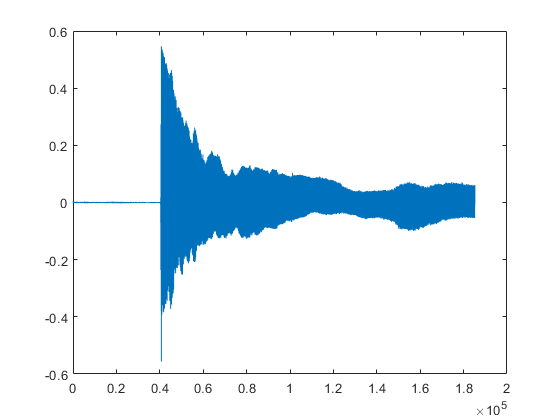

clear
clc
tic
[y1,f1]=audioread('A_tuned.wav');
sz=size(y1);
Nfft=sz(1,1)+1;
y=y1([1:Nfft-1],[1:1]);

plot(y)

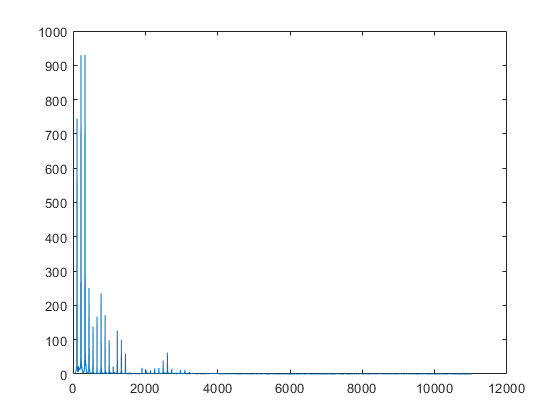

%y=y(21000:21000+1024,1)

t=linspace(0,length(y)/f1,length(y));
 %power of 2 and I put a huge number so there are many data points
f=linspace(0,f1,Nfft);
X1=movmean(abs(fft(y,Nfft)),13);
plot(f(1:round(Nfft/2)),X1(1:round(Nfft/2)))

laval=zeros(1,6);
xval=zeros(6,1);
minamp = 50; %Arbitriarily choosen value for minimu amplitude.
maxfreqpos = zeros(1,20);
maxamps=zeros(1,8);
freqtest=zeros(1,3);
halfNfft=Nfft/2;
for i=2:halfNfft
    x11=X1(i,1);
    if x11>50
        if (x11>laval(1,6)) && (X1(i-1,1)<=x11) && (X1(i+1,1)<=x11)
            for k=1:+1:6
                if x11> laval(1,k)
                    for kk=5:-1:k
                        laval(1,kk+1)=laval(1,kk);
                        xval(kk+1,1)=xval(kk,1);
                        maxfreqpos(1,kk+1)=maxfreqpos(1,kk);
                    end
                    maxfreqpos(1,k)=i;
                    laval(1,k)=x11;
                    xval(k,1)=f(1,i);
                    break;
                end 
            end
        end
    end
end
chordfreq=zeros(1,6); 
for num=1: 6
kk=1;
frequencies=zeros(1,20);  
%for ii=20: -1: 1 %This function find "harmonics" at lower frequencies than the max amplitude frequency
ii=1;
while (xval(num,1)/kk>20)
    x12=X1(round(maxfreqpos(1,num)/kk),1);
    if x12 > minamp
        maxamps(1,ii) =  x12;
        frequencies(1,ii) = xval(num,1)/kk;
        ii=ii+1;
    end
    kk=kk+1;
end
%  while frequencies(1,1) == 0 %This part moved the numbers in the matrix towards the start.
%     for i=1: +1: 7 %It also leaves a trail of numbers as it does not clean up after itself
%         frequencies(1,i)=frequencies(1,i+1);
%     end
%  end
% for kkk=1: +1: 7  %This part removed all numbers that have been left as a 
%     %trail in the matrix. Any numbers that are double will be removed.
%    if frequencies(1,kkk) == frequencies(1,kkk+1)
%        for i=kkk: +1: 8
%            frequencies(1,i+1)=0;
%            
%        end
%        break;
%    end
% end
frequencies=sort(frequencies,'ascend');
ik=find(frequencies>0);
chordfreq(1,num) = frequencies(1,ik(1,1));
end
 
% for k=1:6 %sort values to be from largest to lowest
%     if chordfreq(1,k)>sortfreq(1,6)
%         for i=1:+1:6
%             if chordfreq(1,k)> sortfreq(1,i)
%                 for kk=5:-1:i
%                     sortfreq(1,kk+1)=sortfreq(1,kk);
%                 end
%                 sortfreq(1,i)=chordfreq(1,k);
%                 flag=1;
%             end 
%             if flag==1
%                 flag=0;
%                 break;
%             end
%         end
%     end
% end
sortfreq=sort(chordfreq,'descend');

for k=1:5 %eliminate close to identical values
    if (sortfreq(1,k) > sortfreq(1,k+1)-5) && (sortfreq(1,k) < sortfreq(1,k+1)+5)
        sortfreq(1,k+1)=0;
    end 
    sortfreq=sort(sortfreq,'descend');

end
toc

Elapsed time is 4.704248 seconds.
